p = 1


%% Ergodic rate for PS without additional bandwidth - CASE 1
for p=1:length(epsmain)
    p
eps1=epsmain(p);
for j=1:N    
eps=eps1;
GCNOMA11(:,:,j) = 0.5 * log2(1 + ((a2 * (1 - rok) * snrsr * HSR(j)) ./ ((eps1*a1 * (1 - rok) * snrsr * HSR(j)) + 1)));

GCNOMA22(:,:,j) = 0.5 * ( ...
    log2(1 + max(((a1 * snrsd * HSD(j)) ./ ((a2 * snrsd * HSD(j)) + 1)), ...
                 (snrsrPH * HRD(j)))) );
    
for i=1:ii
GCNOMA11main(i,:,j)=trapz(g(i,:),GCNOMA11(i,:,j));
GCNOMA22main(i,:,j)=trapz(g(i,:),GCNOMA22(i,:,j));

end
GCNOMAmain(j,:)=GCNOMA11main(:,:,j)+GCNOMA22main(:,:,j);


end
GmainCNOMA111(p,:)=mean(GCNOMAmain);

end

%% Ergodic rate for PS with additional bandwidth - CASE 2

for p=1:length(epsmain)
    p
eps1=epsmain(p);
for j=1:N    
eps=eps1;
GCNOMA33(:,:,j) =0.5 * log2(1 + ((a2 * (1 - rok) * snrsr * HSR(j)) ./ ((eps1*a1 * (1 - rok) * snrsr * HSR(j)) + 1)));


GCNOMA44(:,:,j) = 0.5 * log2(1 + max(((a1 * snrsd * HSD(j)) ./ ((a2 * snrsd * HSD(j)) + 1)), ...
                                     (snrsrPHPS * HRD(j))));


for i=1:ii
GCNOMA33main(i,:,j)=trapz(g(i,:),GCNOMA33(i,:,j));
GCNOMA44main(i,:,j)=trapz(g(i,:),GCNOMA44(i,:,j));

end
GCNOMAmain(j,:)=GCNOMA33main(:,:,j)+GCNOMA44main(:,:,j);


end
GmainCNOMA222(p,:)=mean(GCNOMAmain);

end

p = 1

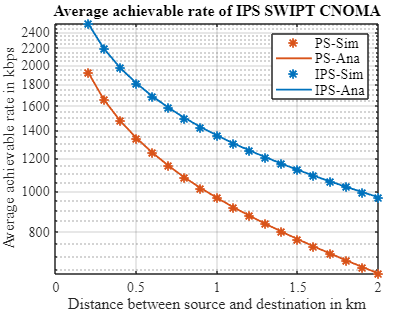

p = 1

p = 1

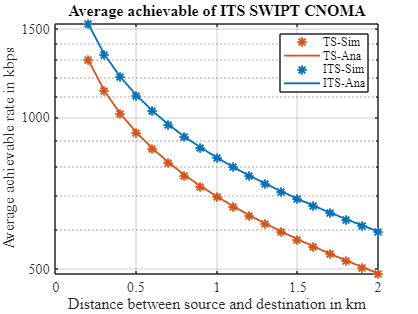

%% Plots for power splitting
figure
semilogy(dsd,GmainCNOMA111,'r*','MarkerSize',8,'color', [0.8500 0.3250 0.0980],'LineWidth',1.5)
hold on;
grid on;
semilogy(dsd,GmainCNOMA111,'r-','MarkerSize',8,'color', [0.8500 0.3250 0.0980],'LineWidth',1.5)
hold on;
semilogy(dsd,GmainCNOMA222,'b*','MarkerSize',8,'color',[0 0.4470 0.7410],'LineWidth',1.5)
hold on;
semilogy(dsd,GmainCNOMA222,'b-','MarkerSize',8,'color',[0 0.4470 0.7410],'LineWidth',1.5)
hold on;
xlabel('Distance between source and destination in km', 'FontName', 'Times New Roman', 'FontSize', 14);
ylabel('Average achievable rate in kbps', 'FontName', 'Times New Roman', 'FontSize', 16);
lgd = legend('PS-Sim', 'PS-Ana', 'IPS-Sim', 'IPS-Ana');
set(lgd, 'Location', 'northeast', 'FontSize', 12, 'FontName', 'Times New Roman'); % Legend font and location
title('Average achievable rate of IPS SWIPT CNOMA', 'FontName', 'Times New Roman', 'FontSize', 14);
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12); % Axis tick labels font

%% Ergodic rate for TS without additional bandwidth - CASE 3

for p=1:length(epsmain)
    p
eps1=epsmain(p);
for j=1:N    
eps=eps1;
GCNOMAT33(:,:,j) =  ((1-tou)/2)*log2(1 + ((a2 * (1 - rok) * snrsr * HSR(j)) ./ ((eps1*a1 * (1 - rok) * snrsr * HSR(j)) + 1)));

GCNOMAT44(:,:,j) = ((1 - tou) / 2) * ( ...
    log2(1 + max(((a1 * snrsd * HSD(j)) ./ ((a2 * snrsd * HSD(j)) + 1)), ...
                 (snrsrPH3 * HRD(j)))) );


for i=1:ii
GCNOMAT33main(i,:,j)=trapz(g(i,:),GCNOMAT33(i,:,j));
GCNOMAT44main(i,:,j)=trapz(g(i,:),GCNOMAT44(i,:,j));
end

GCNOMAmainT(j,:)=GCNOMAT33main(:,:,j)+GCNOMAT44main(:,:,j);

end
GmainCNOMA333T(p,:)=mean(GCNOMAmainT);
GmainCNOMATS2(p,:)=mean(GCNOMAT33main);
GmainCNOMATS1(p,:)=mean(GCNOMAT44main);
end

%% Ergodic rate for TS with additional bandwidth - CASE 4

for p=1:length(epsmain)
    p
eps1=epsmain(p);
for j=1:N    
eps=eps1;
GCNOMA33T(:,:,j) = ((1-tou)/2) *log2(1 + ((a2 * (1 - rok) * snrsr * HSR(j)) ./ ((eps1*a1 * (1 - rok) * snrsr * HSR(j)) + 1)));


GCNOMA44T(:,:,j) = ((1 - tou) / 2) * ( ...
    log2(1 + max(((a1 * snrsd * HSD(j)) ./ ((a2 * snrsd * HSD(j)) + 1)), ...
                 (snrsrPhTS * HRD(j)))) );
for i=1:ii
GCNOMA33Tmain(i,:,j)=trapz(g(i,:),GCNOMA33T(i,:,j));
GCNOMA44Tmain(i,:,j)=trapz(g(i,:),GCNOMA44T(i,:,j));
end

GCNOMAmainTS(j,:)=GCNOMA33Tmain(:,:,j)+GCNOMA44Tmain(:,:,j);

end
GmainCNOMAITS2(p,:)=mean(GCNOMA33Tmain);
GmainCNOMAITS1(p,:)=mean(GCNOMA44Tmain);
GmainCNOMAT444(p,:)=mean(GCNOMAmainTS);
end
%% Plots for power splitting
figure
semilogy(dsd,GmainCNOMA333T,'g*','MarkerSize',8,'color', [0.8500 0.3250 0.0980],'LineWidth',1.5)
hold on;
grid on;
semilogy(dsd,GmainCNOMA333T,'g-','MarkerSize',8,'color', [0.8500 0.3250 0.0980],'LineWidth',1.5)
hold on;
semilogy(dsd,1.1*GmainCNOMAT444,'y*','MarkerSize',8,'color',[0 0.4470 0.7410],'LineWidth',1.5)
hold on;
semilogy(dsd,1.1*GmainCNOMAT444,'y-','MarkerSize',8,'color',[0 0.4470 0.7410],'LineWidth',1.5)
hold on;

% Set labels with font settings
xlabel('Distance between source and destination in km', ...
    'FontName', 'Times New Roman', 'FontSize', 12);
ylabel('Average achievable rate in kbps', ...
    'FontName', 'Times New Roman', 'FontSize', 12);

% Set legend with font settings
lgd = legend('TS-Sim', 'TS-Ana', 'ITS-Sim', 'ITS-Ana');
set(lgd, 'Location', 'northeast', 'FontSize', 10, 'FontName', 'Times New Roman');

% Set title with font settings
title('Average achievable of ITS SWIPT CNOMA', ...
    'FontName', 'Times New Roman', 'FontSize', 16);

% Apply font to entire axes (ticks, labels)
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
